# Opgave 1: Gram-Schmidt

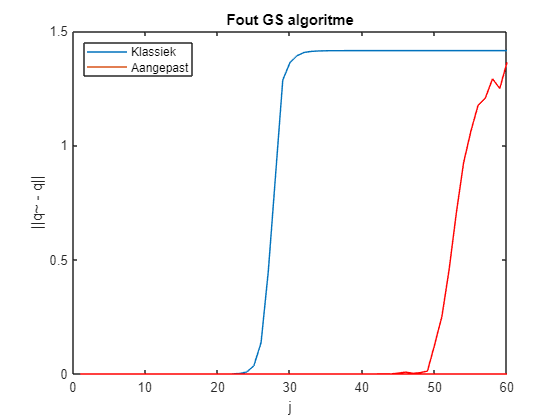

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V;

% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') 

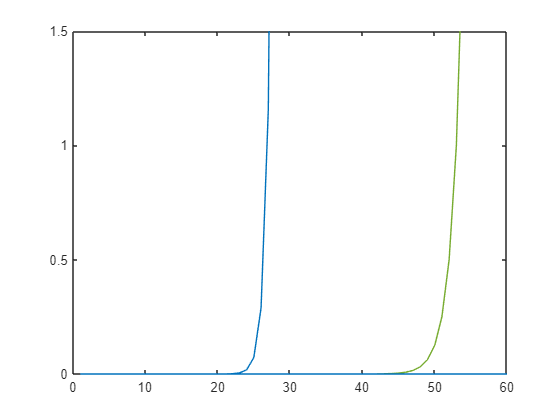


% Oefening 5
te1 = zeros(n);
te2 = zeros(n);
x = zeros(1,n);
for j = 1:n
    x(j) = 2^(j-1);
    te1(j) = 2^(j-1)*norm(x)*eps;
    te2(j) = 2^(j-1)*eps;
end
plot(te1)
hold on
plot(te2)
hold off
axis([0 60 0 1.5])

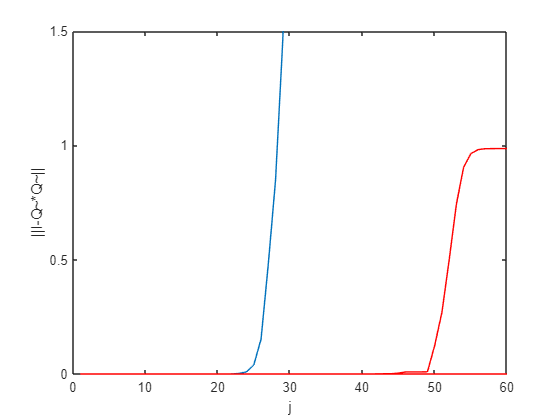


% Oefening 8
orth1 = zeros(n);
orth2 = zeros(n);

for j = 1:n
    orth1(j) = norm(eye(j) - transpose(Q1(:,1:j))*Q1(:,1:j));
    orth2(j) = norm(eye(j) - transpose(Q2(:,1:j))*Q2(:,1:j));
end

plot(orth1)
hold on
plot(orth2,'Color','r')
hold off
xlabel('j')
ylabel('||I-Q~*Q~||')
axis([0 60 0 1.5])

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)


% Oefening 9
m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

V = randn(n); % change this to orthogonal matrix

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A

A = A(:,:,1) =

   -0.5579    1.7720    0.7738    0.6625    1.7215   -0.1061   -1.1897   -2.1412   -0.3272    0.6328    0.4029    0.2931   -0.0774   -0.5048   -0.3004    0.5542   -1.0118   -0.2620   -0.3044   -0.6741   -0.6090   -0.2062    0.4515    0.6068   -0.9714    0.4787   -1.2948   -0.1638   -0.0572    0.7356   -0.7467   -0.6498   -0.8357   -0.5101   -0.9322   -0.7809    0.1696    0.3975   -0.7675    0.6913   -0.1712   -0.2303    0.5470    0.2005    0.5055   -0.2639   -0.6732   -0.1983   -0.7709   -0.8037
   -1.9988    0.9850   -1.4600   -0.4843   -1.8045   -0.5825   -0.6745    0.1310    0.5897    0.7412   -1.0316   -0.7241    0.4841   -0.6823    0.2840   -0.1230   -0.6698    0.5683    0.8760   -0.9113   -0.1438    0.0341    1.7092    0.6994    0.0338    0.5627    0.6192    0.8402    0.7045    0.0732   -1.5494    1.0468   -0.4330   -0.1900    0.5031    1.0966    0.3942    1.2652   -1.4499    0.1086    0.6137    0.2745    1.0220   -0.8750   -0.2433   -1.1459   -0.9563   -0.1581   

K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1

Q1 = Q1(:,:,1) =

   -0.0595    0.1774    0.1032    0.0881    0.1506   -0.0353   -0.1408   -0.1943   -0.0508    0.0124   -0.0313    0.0560   -0.0312   -0.0125   -0.0825    0.0023   -0.0998   -0.0535    0.1121    0.0501   -0.1287    0.0144    0.1249   -0.0045    0.0001    0.0556   -0.0144    0.0213   -0.0192    0.0236   -0.0310    0.0510   -0.0917    0.0806   -0.0957   -0.0223   -0.0148   -0.0101    0.0206   -0.0225   -0.1581   -0.0450   -0.0419    0.0279   -0.0318   -0.0434    0.0326    0.0334    0.1079    0.0782
   -0.2132    0.0910   -0.1142   -0.0472   -0.1093   -0.0743   -0.1165   -0.0130    0.0243   -0.0670   -0.0621    0.0010    0.0652   -0.0583   -0.0423    0.0224   -0.0177    0.0686    0.1385   -0.0176   -0.0083    0.0986    0.0460    0.0544    0.1061   -0.0455    0.0296   -0.0444    0.1342    0.0034   -0.0340    0.0463   -0.1769    0.0435   -0.0106    0.0606   -0.0292    0.1653   -0.1006    0.1341   -0.0034    0.0421   -0.0496   -0.0365   -0.1119   -0.0762   -0.0101   -0.1045 


Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2

Q2 = Q2(:,:,1) =

   -0.0595    0.1774    0.1032    0.0881    0.1506   -0.0353   -0.1408   -0.1943   -0.0508    0.0124   -0.0313    0.0560   -0.0312   -0.0125   -0.0825    0.0023   -0.0998   -0.0535    0.1121    0.0501   -0.1287    0.0144    0.1249   -0.0045    0.0001    0.0556   -0.0144    0.0213   -0.0192    0.0236   -0.0310    0.0510   -0.0917    0.0806   -0.0957   -0.0223   -0.0148   -0.0101    0.0206   -0.0225   -0.1581   -0.0450   -0.0419    0.0279   -0.0318   -0.0434    0.0326    0.0334    0.1079    0.0782
   -0.2132    0.0910   -0.1142   -0.0472   -0.1093   -0.0743   -0.1165   -0.0130    0.0243   -0.0670   -0.0621    0.0010    0.0652   -0.0583   -0.0423    0.0224   -0.0177    0.0686    0.1385   -0.0176   -0.0083    0.0986    0.0460    0.0544    0.1061   -0.0455    0.0296   -0.0444    0.1342    0.0034   -0.0340    0.0463   -0.1769    0.0435   -0.0106    0.0606   -0.0292    0.1653   -0.1006    0.1341   -0.0034    0.0421   -0.0496   -0.0365   -0.1119   -0.0762   -0.0101   -0.1045 


Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3

Q3 = Q3(:,:,1) =

   -0.0595    0.1747    0.1359    0.0802    0.1657   -0.0691   -0.1098   -0.1253   -0.0668   -0.0374   -0.1185    0.1286   -0.0322   -0.0009   -0.1636   -0.0613   -0.0850   -0.0878    0.1424    0.0900   -0.0755    0.0612    0.1818   -0.1099    0.0893    0.0086    0.1383   -0.1784   -0.0614    0.0226    0.0885    0.0689   -0.0107    0.0148   -0.0116    0.0404    0.0574   -0.0248    0.0099   -0.0615   -0.0593   -0.0365   -0.0196    0.0444   -0.1103    0.0745    0.1264   -0.0514    0.1022    0.1542
   -0.2132    0.0819   -0.1045   -0.0200   -0.0803   -0.0616   -0.1377   -0.0406    0.0089   -0.1536    0.0011    0.0789    0.0087   -0.0018   -0.1457    0.0422   -0.0066    0.0027    0.1570    0.1274   -0.0996    0.1559    0.1024   -0.0898    0.1462   -0.0210    0.1357   -0.1249   -0.0876    0.1095    0.1398   -0.0103   -0.0994   -0.0682   -0.1172    0.0829    0.1059    0.1096   -0.0812   -0.1244    0.0866    0.0285   -0.0160    0.1226   -0.0878    0.1327    0.1434    0.0647 


orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i).'*Q1(:,:,i));
end
orth1

orth1 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i).'*Q2(:,:,i));
end
orth2

orth2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i).'*Q3(:,:,i));
end
orth3

orth3 =    21.7399
   30.6799
   32.6976
   36.7779
   38.7835
   37.5306
   34.6494
   32.8230
   30.4188
   28.1365


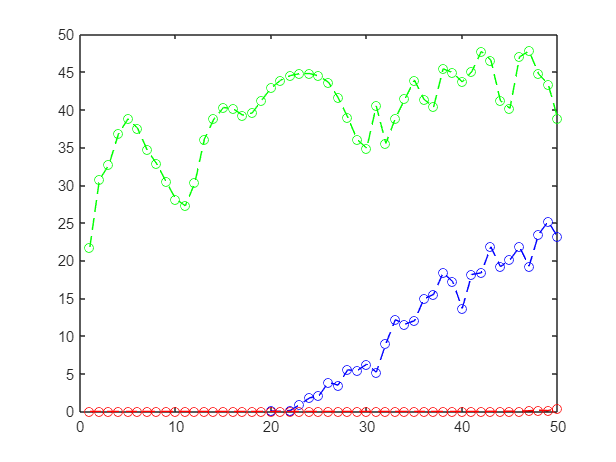


plot(k, orth1, 'b--o', k, orth2, 'r--o', k, orth3, 'g--o')


%Fout is veel te groot voor KLGS en herGS, kan niet!


% Oefening 11
eps

ans = 2.2204e-16

eps/0.83

ans = 2.6752e-16

0.83-eps

ans = 0.8300

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m);

